%{

Element Predictor 2000: 

A program for use with cubic-crystal x-ray diffraction data.
Written by Colin Merkel.

Usage:

elementPredictor2000( X_RAY_WAVELENGTH, ARRAY_OF_DISTANCES)

Parameters:

X_RAY_WAVELENGTH: 

The wavelength of the x-rays in Angstroms 

ARRAY_OF_DISTANCES: 

This is a one-dimensional vector of arbitrary length, containing
data values corresponding to the distances in centimeters from the exit
port of the x-rays to each line. If you can't remember which hole on the 
tape represents the exit port, that's okay, this program can probably 
figure out that mistake and fix it.

What it does:

The program "guesses" a lattice spacing constant and tries to best fit the
data you gave it to the constant. The "quality" of that guess is computed.
All lattice spacing constants are guessed within a reasonable range. The
guess with the best "quality" (q<0.1 corresponds to good quality) is taken
as the value for the lattice spacing.

A lookup table is used to determine which elements have lattice spacing
parameters near the best guess. A series of possible matches are shown. The
possible d-values are computed via the Bragg law and printed out for easy
reference

Once a few possible guesses are given by the program, the best course of
action is to look up the three expected highest intensity d-values for each
element that the program guessed using the system of cards.
 
If three of the d-parameters match up with the guess, you've found your
element.

%}
lengthList = [15.66298343,44.50276243,51.96132597,75.33149171,91.24309392,96.21546961,117.0994475,137.9834254,145.441989]

lengthList =    15.6630   44.5028   51.9613   75.3315   91.2431   96.2155  117.0994  137.9834  145.4420


ans = 'Calculating data...'

ans = 'Halfway done...'

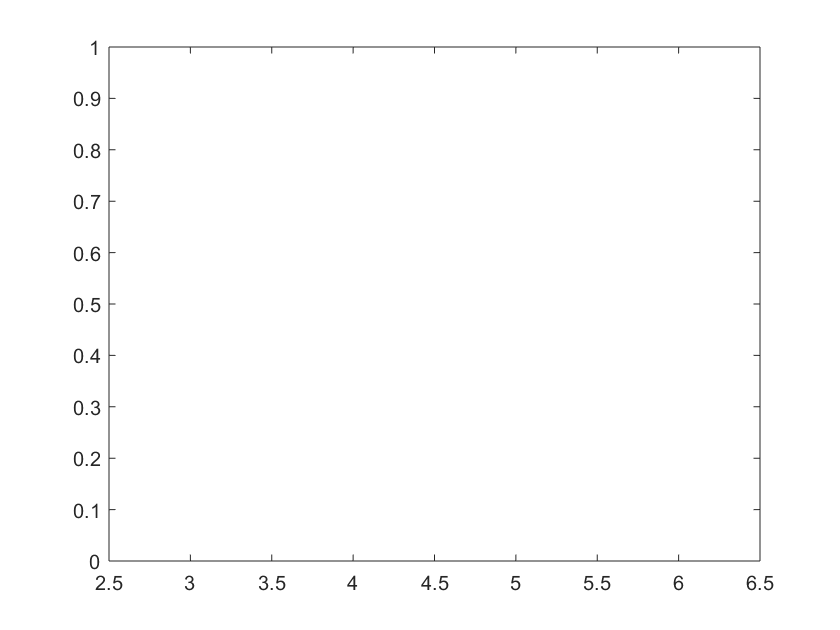

debug = 5.7084e+04

ans = 'Looks like you got the orientation right'

ans = 'Results do not look very conclusive'

ans = 'Finding element...'

ans = 'Init high resoution search...'

ans = 'Conclusion: lattice constant is 4.002360e+00 angstroms.'

ans = 'Could be Aluminum... (within 4.714000e-02 angstrom)'

ans = 'Here are your d-values: look up the values in the cards, see if you can match them to these'

d =     0.7849    0.7703    0.7703    0.7703    0.7703    0.7703    0.7703    0.7703    0.7703



elementPredictor2000(1.54051,lengthList);

function [] = elementPredictor2000(lambda,dists)
    % List of cube sums
    p = [1,2,3,4,5,6,8,9,10,11,12,13,14,16,17,18,19,20,21,22,24,25,26,27,29];
    % List of elements in order of lattice constant
    element_const = [2.8665;2.91000000000000;3.00500000000000;3.03000000000000;3.14700000000000;3.16500000000000;3.30040000000000;3.30130000000000;3.30900000000000;3.35900000000000;3.51000000000000;3.52400000000000;3.61500000000000;3.80300000000000;3.83900000000000;3.89000000000000;3.92400000000000;4.04950000000000;4.07820000000000;4.08530000000000;4.24400000000000;4.29000000000000;4.42900000000000;4.58100000000000;4.95000000000000;5.02800000000000;5.06000000000000;5.08420000000000;5.14800000000000;5.32800000000000;5.43090000000000;5.48470000000000;5.58840000000000;5.65750000000000;5.67000000000000;5.83180000000000;6.08490000000000;6.14100000000000;];
    % List of associated element names
    element_names = {'Iron','Chromium','Mercury','Vanadium','Molybdenum','Tungsten','Niobium','Tantalum','Scandium','Polonium','Lithium','Nickel','Copper','Rhodium','Iridium','Palladium','Platinum','Aluminum','Gold','Silver','Helium','Sodium','Neon','Europium','Lead','Barium','Boron','Thorium','Radium','Potassium','Silicon','Ytterbium','Calcium','Germanium','Actinium','Tin','Strontium','Cesium';};

    % Assume distance data is correctly aligned. Try to generate data.
   
    'Calculating data...'
    [x,y1] = doTheThing(p,lambda,dists);
    dists = 18-dists;
    'Halfway done...'
    [x,y2] = doTheThing(p,lambda,dists);
    debug = min(y1)
    if(min(y1) < min(y2)) 
        sprintf('Looks like you got the orientation right')
        dists = 18-dists;
    else
        sprintf('Looks like you got the orientation WRONG, but I fixed it...')
        y1 = y2;
    end
    minval = min(y1);
    if(minval < 0.1) 
        sprintf('Results look conclusive.')
    else
        sprintf('Results do not look very conclusive')
    end
    
    sprintf('Finding element...')
    for j = 1:length(y1)
        if(y1(j) == minval)
            break
        end
    end
    if(j == length(y1))
        sprintf('Error: WTF')
        return
    end
    a = x(j);
    
    sprintf('Init high resoution search...') % added Nov. 22 for ultra resolution
    [x,y] = doTheHighResThing(p,lambda,dists,a);
    
    minval = min(y);
    
    for j=1:length(y) 
        if(y(j) == minval)
            break
        end
    end
    if j==length(y)
        sprintf('Error: WTF 2')
        return
    end
    
    a = x(j);
    
    sprintf('Conclusion: lattice constant is %d angstroms.',a)
    
    didFindElement = 0;
    for j=1:length(element_const)
        e = abs(element_const(j)-a);
        if(e < .05)
            sprintf('Could be %s... (within %d angstrom)',element_names{j},e)
            didFindElement=1;
        end
    end    
    
    if (didFindElement ==0) 
        sprintf('I could not find your element!')
    end
    
    'Here are your d-values: look up the values in the cards, see if you can match them to these'
    
    for j=1:length(dists)
       [uiop,is] = doTheThings(p,lambda,a,dists(j));
       d(j) = a / sqrt(is);
    end
    d
    
end

function [x,y] = doTheHighResThing(p,lambda,dists,a) %same as diTheThing but higher res
       
    x = 1:1000;
    x = x * (0.02/1000);
    x = x + a - 0.01;
    
    for j=1:1000
        y(j) = FitnessOfA(p,lambda,x(j),dists);
    end
    
end
function [x,y] = doTheThing(p,lambda,dists) %plots the fitness of the a value vs the a value for a list of dists
    x = 1:1000;
    x = x*0.004;
    x = x + 2.5;
    for j=1:1000
        y(j) = FitnessOfA(p,lambda,x(j),dists);
    end
    
    plot(x,y)
    axis([2.5 6.5 0 1])
end

function [e] = FitnessOfA(p,lambda,a,dists) %determines the fitness of an a value for a list of distances
    for j=1:length(dists)
       [ers(j),is(j)] = doTheThings(p,lambda,a,dists(j));
    end
    e = sum(ers);
end

function [e,i] = doTheThings(p,lambda,a,dist)%returns the square error in distance between predicted and actual for that a value, as well as the cube associated with that a value
    for j = 1:length(p) % try the different hkl, see which dist is closest
        if(generateLine(lambda,a,p(j)) > dist)
            break % we found the breaking point
        end
    end
    if(j == 1) 
        j = 2; % prevent some error
    end
    if(j == length(p)) 
        j = length(p) - 1; % prevent opposite error
    end
    
    aq = abs(dist - generateLine(lambda,a,p(j-1)));
    bq = abs(dist - generateLine(lambda,a,p(j)));
    
    if(aq<bq) 
        e=aq^2; 
        i=p(j-1);
    else
        e=bq^2;
        i = p(j);
    end
end

function [l] = generateLine(lambda,a,hkl) %gives a line marking in cm 
   l = sqrt(hkl)*lambda/(2*a);
   l = (180/pi)*asin(l);
   l = l * 2 / 10;
end
